% t = asss.Time;
% alplqr = asss.Data;
% xclqr = movesss.Data(:,2);

% alpplace = asss.Data;
% xcplace = movesss.Data(:,2);
% plot(t,alplqr)
% title("Alpha vs Time")
% xlabel('Time, s')
% ylabel('Angle, deg')
% hold on
% plot(t,alpplace)
% legend("LQR","Place")
% xlim([0,3.5])
% hold off
% 
% plot(t,xclqr)
% hold on
% title("Position vs Time")
% xlabel('Time, s')
% ylabel('Location, mm')
% plot(t,xcplace)
% legend("LQR","Place")
% hold off
Kplace = place(A,B,[-4,-8,-1,-7]);
Klqr = lqr(A,B,diag([25 30 10 15]),3);
polesplace = eig(A-B*Kplace)

polesplace =    -8.0000
   -7.0000
   -4.0000
   -1.0000


poleslqr = eig(A-B*Klqr)

poleslqr =  -20.9894 + 0.0000i
  -4.5577 + 2.0083i
  -4.5577 - 2.0083i
  -0.3689 + 0.0000i


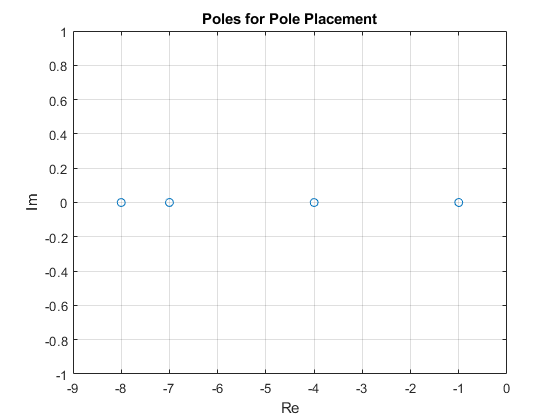


plot(real(polesplace),imag(polesplace),'o')
grid on
title("Poles for Pole Placement")
xlabel("Re")
ylabel("Im")

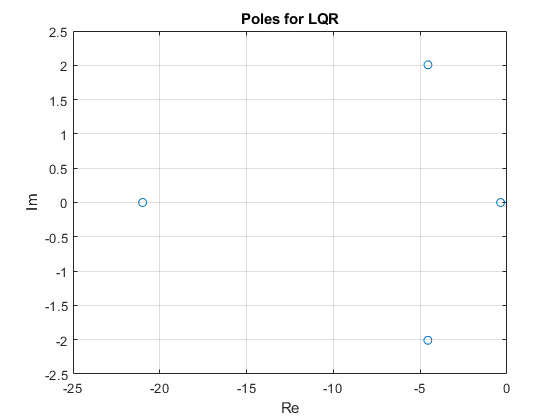


plot(real(poleslqr),imag(poleslqr),'o')
title("Poles for LQR")
xlabel("Re")
ylabel("Im")
grid on